clear all; close all; clc;
%%%%%%%%%ALLOCATIONS%%%%%%%%%%
global Frame_Buf
Frame_Buf = zeros(480,640);
%%%%%%%%%%STATES%%%%%%%%%%%%%%%
middle_dot_0 = 8;
random_line = 9;
read_0 = 10;
read_1 = 11;
read_2 = 12;
read_3 = 13;
read_4 = 14;
x_bound_0 = 15;
wait_cycle = 16;
stop_FSM = 17;
read_0_left_boundary = 18;
read_2_right_boundary = 19;
y_bound_0 = 20;
decide = 21;
%%%%%%%%%%%INITIALS%%%%%%%%%%%%
%|SW6||SW5||SW4||SW3||SW2||SW1|
%   0   0   0     1     0   1
%   ->5
SW = zeros(1,18)

SW =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0



sum = 0

sum = 0

SW(1,18) = 0

SW =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


debug_stop = 1

debug_stop = 1

reset = 1

reset = 1

flag = 1

flag = 1

SW(1,1:8) = rule_SW(110)

SW =      0     1     1     1     0     1     1     0     0     0     0     0     0     0     0     0     0     0


cycle = 0

cycle = 0

%ad_fr(x,y)
rule3 = [0 0 0]

rule3 =      0     0     0


sho_im = 0

sho_im = 0

counter_fsm_x_initial = 1;
counter_fsm_y_initial = 2;
        
counter_fsm_y = 0

counter_fsm_y = 0

counter_fsm_x = 1

counter_fsm_y = 2

rand_num = 1

rl_flag = 0

lf_flag = 0

state = 8

reset = 0

sho_im = 1

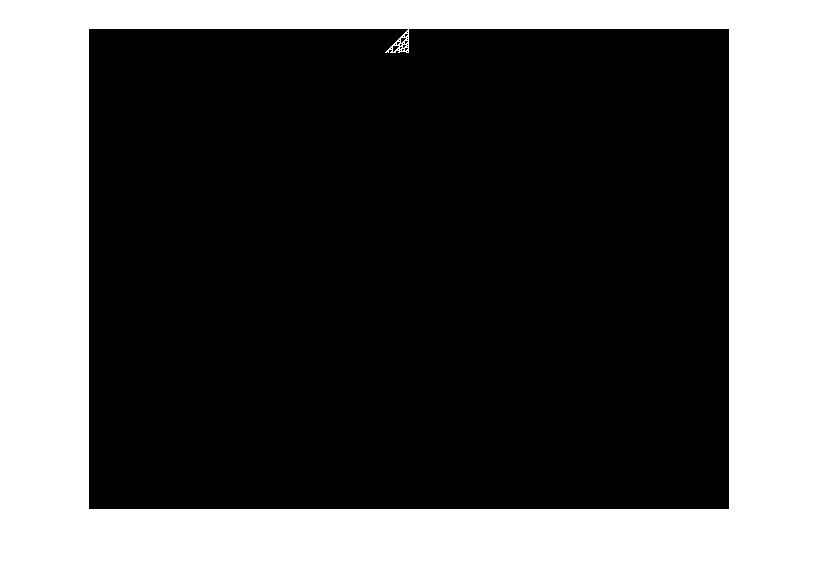

while(debug_stop)
    rand_num = randi([0 1]);

    if(reset)
        counter_fsm_x = counter_fsm_x_initial
        counter_fsm_y = counter_fsm_y_initial
        rand_num = randi([0 1])
        
        rl_flag = 0
        lf_flag = 0
        
        if(~SW(1,18))
            state = middle_dot_0
        else
            state = random_line
        end
        reset = 0%%
    else
        switch state
            case middle_dot_0
                address_a = ad_fr(320,1);
                data_a_0 = 1;
                wren_a = 1;
                Frame_Buffer(address_a, data_a_0, wren_a, sho_im);
                state = read_0_left_boundary;
                
            case random_line
                if(counter_fsm_x ~= 641)
                    address_a = ad_fr(counter_fsm_x,1);
                    data_a_0 = rand_num;
                    wren_a = 1;
                    Frame_Buffer(address_a, data_a_0, wren_a, sho_im);
                    state = random_line;  
                    counter_fsm_x = counter_fsm_x + 1;
                else
                    wren_a = 0;
                    counter_fsm_x = counter_fsm_x_initial;
                    state = read_0_left_boundary;  
                end
            case read_0_left_boundary
                wren_a = 0;
                address_a = ad_fr(640, counter_fsm_y - 1);
                Frame_Buffer(address_a, data_a_0, wren_a, sho_im);     
                state = read_1;
                
            case read_0
                wren_a = 0;
                address_a = ad_fr(counter_fsm_x - 1, counter_fsm_y - 1);
                Frame_Buffer(address_a, data_a_0, wren_a, sho_im);                
                state = read_1;

            case read_1
                wren_a = 0;
                address_a = ad_fr(counter_fsm_x, counter_fsm_y - 1);
                Frame_Buffer(address_a, data_a_0, wren_a, sho_im);
                if rl_flag
                    state = read_2_right_boundary;
                else
                    state = read_2;
                end
                
            case read_2
                wren_a = 0;
                address_a = ad_fr(counter_fsm_x + 1, counter_fsm_y - 1);
                rule3(1) = Frame_Buffer(address_a, data_a_0, wren_a, sho_im);
                state = read_3;
             
            case read_2_right_boundary
                wren_a = 0;
                address_a = ad_fr(1, counter_fsm_y - 1);
                rule3(1) = Frame_Buffer(address_a, data_a_0, wren_a, sho_im);
                state = read_3;
                
            case read_3 %address is the middle
                wren_a = 0;
                address_a = ad_fr(counter_fsm_x, counter_fsm_y);
                rule3(2) = Frame_Buffer(address_a, data_a_0, wren_a, sho_im);
                state = read_4;
                
            case read_4%address is the middle
                wren_a = 0;
                address_a = ad_fr(counter_fsm_x, counter_fsm_y);
                rule3(3) = Frame_Buffer(address_a, data_a_0, wren_a, sho_im);
                state = toDecimal(rule3);
               
            case 0%000
                wren_a = 1;
                data_a_0 = SW(1,1);
                address_a = ad_fr(counter_fsm_x, counter_fsm_y);
                Frame_Buffer(address_a, data_a_0, wren_a, sho_im);
				state = x_bound_0;

            case 1%001
                wren_a = 1;
                data_a_0 = SW(1,2);
                address_a = ad_fr(counter_fsm_x, counter_fsm_y);
                Frame_Buffer(address_a, data_a_0, wren_a, sho_im);
				state = x_bound_0;
            case 2%010
                wren_a = 1;
                data_a_0 = SW(1,3);
                address_a = ad_fr(counter_fsm_x, counter_fsm_y);
                Frame_Buffer(address_a, data_a_0, wren_a, sho_im);
				state = x_bound_0;

            case 3%011
                wren_a = 1;
                data_a_0 = SW(1,4);
                address_a = ad_fr(counter_fsm_x, counter_fsm_y);
                Frame_Buffer(address_a, data_a_0, wren_a, sho_im);
				state = x_bound_0;

            case 4%100
                wren_a = 1;
                data_a_0 = SW(1,5);
                address_a = ad_fr(counter_fsm_x, counter_fsm_y);
                Frame_Buffer(address_a, data_a_0, wren_a, sho_im);
				state = x_bound_0;

            case 5%101
                wren_a = 1;
                data_a_0 = SW(1,6);
                address_a = ad_fr(counter_fsm_x, counter_fsm_y);
                Frame_Buffer(address_a, data_a_0, wren_a, sho_im);
				state = x_bound_0;

            case 6%110
                wren_a = 1;
                data_a_0 = SW(1,7);
                address_a = ad_fr(counter_fsm_x, counter_fsm_y);
                Frame_Buffer(address_a, data_a_0, wren_a, sho_im);
				state = x_bound_0;

            case 7%111
                wren_a = 1;
                data_a_0 = SW(1,8);
                address_a = ad_fr(counter_fsm_x, counter_fsm_y);
                Frame_Buffer(address_a, data_a_0, wren_a, sho_im);
				state = x_bound_0;

            case x_bound_0
                wren_a = 0;
                counter_fsm_x = counter_fsm_x + 1;
                Frame_Buffer(address_a,data_a_0,0,sho_im);
                if(counter_fsm_x == 640)
                    rl_flag = 1;
                else
                    if (counter_fsm_x == 641)%641
                        rl_flag = 0;
                        lf_flag = 1;
                        counter_fsm_x = counter_fsm_x_initial;
                        counter_fsm_y = counter_fsm_y + 1;
                    end
                end
                state = y_bound_0;

            case y_bound_0
                Frame_Buffer(address_a,data_a_0,0,sho_im);
                if(counter_fsm_y == 25)%481%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%<---------
                    state = wait_cycle;
                else
                    state = decide;   
                end
                
            case decide
                Frame_Buffer(address_a,data_a_0,0,sho_im);
                if(lf_flag)
                    lf_flag = 0;
                    state = read_0_left_boundary;
                else
                    state = read_0;
                end
                
            case wait_cycle
                wren_a = 0;
                if(cycle ~= 2)
                    cycle = cycle + 1;
                    Frame_Buffer(address_a,data_a_0,0,sho_im);
                else
                    Frame_Buffer(address_a,data_a_0,0,sho_im);
                    state = stop_FSM;
                end      
                
            case stop_FSM
                    sho_im = 1
                    Frame_Buffer(address_a,data_a_0,wren_a,sho_im)

            otherwise
                disp('other value')
        end
    end
end

function y = toDecimal(A)

    % convert x to a string array
    str_A = num2str(A);
    % remove the spaces in the string, so it 
    % becomes '10000000'
    str_A(isspace(str_A)) = '';
    % now use BIN2DEC to convert the binary 
    % string to a decimal number
    y = bin2dec(str_A);
end



function y = rule_SW(s)
   s = dec2bin(s,8);   
   y = s-'0';
   y = flip(y,2);
end
function q_a_0 = Frame_Buffer(address_a,data_a_0,wren_a_0,sho_im)
    persistent m4k_delay
    persistent q_a_1    
    persistent data_a_1
    persistent x_coor_d_1
    persistent y_coor_d_1
    persistent wren_a_1
    global Frame_Buf

    if(sho_im)
        imshow(Frame_Buf)
    else       
        if isempty(m4k_delay)
            m4k_delay = 1;
            data_a_1 = 0;
        end
            x_coor_b = address_a(1,1:10);
            y_coor_b = address_a(1,11:19);
            x_coor_d_0 = bin2dec(num2str(x_coor_b));
            y_coor_d_0 = bin2dec(num2str(y_coor_b));
            q_a_0 = q_a_1;
            q_a_1 = Frame_Buf(y_coor_d_1, x_coor_d_1);
                    
            if wren_a_1
                Frame_Buf(y_coor_d_1, x_coor_d_1) = data_a_1;
            end
            wren_a_1 = wren_a_0;
            x_coor_d_1 = x_coor_d_0;
            y_coor_d_1 = y_coor_d_0;
            data_a_1 = data_a_0;

    end
end


function y = to_binary_vector(s)
   s = dec2bin(s,8);   
   y = s-'0';
   %msb--------lsb
   %    0000001 -> 1
end
function address = ad_fr(x,y)

    x = dec2bin(x,10);
    y = dec2bin(y,9);
    y = y-'0';
    x = x-'0';
    address = [x y];

end





